# Overview

XL --> X loadings onto components.  ( # X variables  x  # components)

YL --> Y loadings onto componets. ( # Y variables  x  # components)

XS -- > "scores" of each component for each observation of X ( n observations x # components)

YS -- > "scores" of each component for each observation of Y ( n observations x # components)

BETA --> PLSR-calculated regression coefficients. ( #X variables x  #Y variables

W --> PLSR-calulated weights that normalize X.. This is what the SIMPLS algorithm finds. ( # X variables  x  # components)

SIMPLS calculates BETA as:

BETA = W * YL'   

This allows direct prediction of Y from X. 

My data seems better explained when beta is calculated from XL:

Bxl = XL * YL'   =

covariance = X  * Y ' = U * S * V '    

U * S(1:3) ,  ( V * S(1:3) )'

... but the scale is off.

# Categorical

clear all; 

% Load PLSR results. 
load('Y:\Sarah\Analysis\Experiments\Random Motorized Treadmill\PLSR\results\level 1 categorical\Ipsa Contra\motorized_restvswalk\1096\PLSR_results.mat');

% Load dataset
load('Y:\Sarah\Analysis\Experiments\Random Motorized Treadmill\PLSR\variable prep\datasets\level 1 categorical\Ipsa Contra\motorized_restvswalk\1096\PLSR_dataset_info.mat')

holder = NaN(32);
indices = find(tril(ones(32), -1));

XL = PLSR_results.XL;
YL = PLSR_results.YL;
XS = PLSR_results.XS;
YS = PLSR_results.YS;
BETA = PLSR_results.BETA;
W = PLSR_results.stats.W;

X = dataset_info.explanatoryVariables;
Y = dataset_info.responseVariables;


rng = range(Y(:,2));

W0 = W ./ sqrt(sum(W.^2,1));


p = size(XL,1);
sumSq = sum(XS.^2,1).*sum(YL);
vipScore = sqrt(p* sum(sumSq.*(W0.^2),2) ./ sum(sumSq,2));

% Calculate & plot the mean difference between the two periods
% just averages from the original (normalized) dataset.

% (FYI, PLSR captures ~98% of the variation in the correlations for this
% comparison.)
mean_rest = mean(X(Y(:,2) < 0, :),1);
mean_walk = mean(X(Y(:,2) > 0, :),1);
mean_cat_diff_real = (mean_walk - mean_rest)/rng;

% Calculate reconstructed data with W.
XnewW = XS * W';
XSnew = X * W;
YnewW = [ones(size(XnewW,1),1) XnewW]*BETA;

% Calculate mean difference between the two periods for XnewW
% (normalized)
mean_rest = mean(XnewW(Y(:,2) < 0, :),1);
mean_walk = mean(XnewW(Y(:,2) > 0, :),1);
mean_cat_diff_W = (mean_walk - mean_rest)/rng;

% (Note that this XnewW is way too small)


%Calculate reconstructed data with the XL.
XnewXL = XS * XL';

YnewW = [ones(size(XnewW,1),1) XnewW]*BETA; % too small
YnewYL = YS * YL'; % Too small
YnewXL = [ones(size(XnewXL,1),1) XnewXL]*BETA; % Close
YnewXW = [ones(size(X,1),1) X]*BETA; % Close

% Calculate mean difference between the two periods for XnewXL
% (not normalized)
mean_rest = mean(XnewXL(Y(:,2) < 0, :),1);
mean_walk = mean(XnewXL(Y(:,2) > 0, :),1);
mean_cat_diff_XL = (mean_walk - mean_rest)/rng;
%  YnewXW and YnewXL are very similar. 


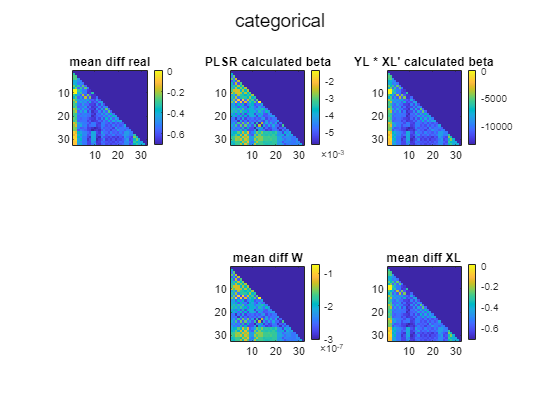

% Plot matrices next to each other.

Bxl = XL * YL';

figure; 
subplot(2, 3, 1);
holder(indices) = mean_cat_diff_real;
imagesc(holder); colorbar; title('mean diff real');axis square;

subplot(2, 3, 2);
holder(indices) = BETA(2:end, 2);
imagesc(holder); colorbar; title('PLSR calculated beta'); axis square;

subplot(2, 3, 3);
holder(indices) = Bxl(:, 2);
imagesc(holder); colorbar; title("YL * XL' calculated beta"); axis square;

subplot(2, 3, 6);
holder(indices) = mean_cat_diff_XL;
imagesc(holder); colorbar; title('mean diff XL'); axis square;

subplot(2, 3, 5);
holder(indices) = mean_cat_diff_W;
imagesc(holder); colorbar; title('mean diff W'); axis square;% Plot each weight.
sgtitle('categorical');

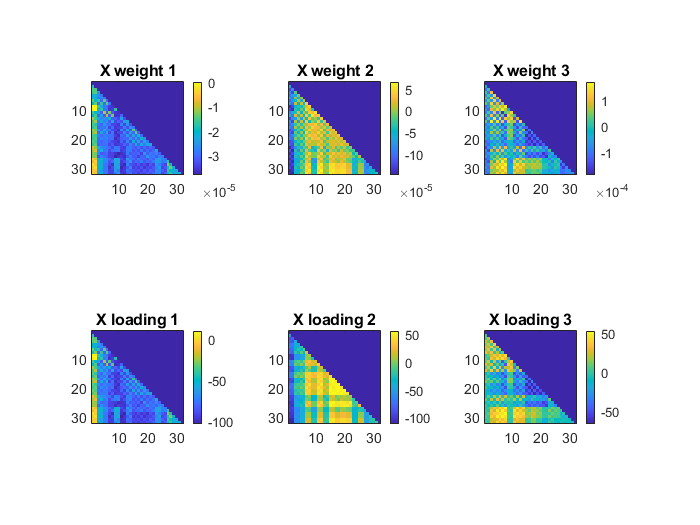

% Plot each weight
figure;
for i = 1:3
    subplot(2,3,i); 
    holder(indices) = W(:,i);
    imagesc(holder); colorbar; axis square; title(['X weight ' num2str(i)]);

    subplot(2,3,i + 3); 
    holder(indices) = XL(:,i);
    imagesc(holder); colorbar; axis square; title(['X loading ' num2str(i)]);

end

% % Try to find scaling factor.
% scale_cat = Bxl' ./ mean_cat_diff_XL;

% % Calculate with B scaling. 
% % (THIS SHOWS THAT YES, THE PATTERN YOUR'RE SEEING CAN BE PULLED FROM W AND
% % B)
% B = XS' * YS;
% beta_rescaled = W * B' * YL';
% 
% bX = ones(size(XL)) * B;
% bY = B * ones(size(YL))';
% 
% holder(indices) = beta_rescaled( :, 2);
% figure; imagesc(holder); colorbar;
% With sum of responseVariables 
% Bpls = XL / sum(abs(Y(:,2))) * 2 * YL';
%  holder(indices) = Bpls(:,2);
%  scale = Bpls' ./ mean_cat_diff_XL;
%  figure; imagesc(holder); colorbar;

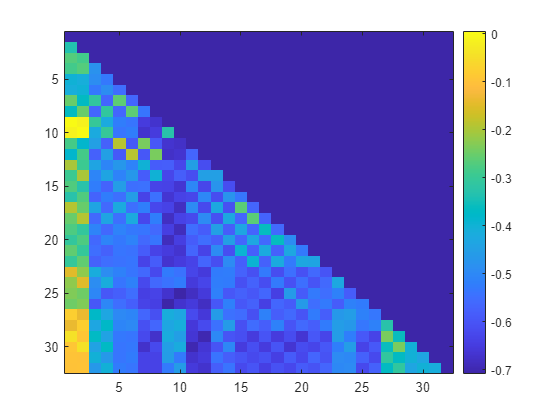

% With un-normalized T (XS)
% [results.XL, results.YL, results.XS, results.YS, results.BETA, results.PCTVAR, results.MSEP, results.stats, results.MSEP_byVars, results.Tnotnormal] ...
%           = plsregress_fullcode(dataset_info.explanatoryVariables, dataset_info.responseVariables, PLSR_results.ncomponents_used); 
% 
% a = PLSR_results.stats.W * (results.Tnotnormal' * results.Tnotnormal) * YL';
% holder(indices) = a(:, 2);
% figure; imagesc(holder); colorbar;

Cov = (X' * Y)/(size(X,1) -1);
holder(indices) = Cov(:,2);
figure; imagesc(holder); colorbar;

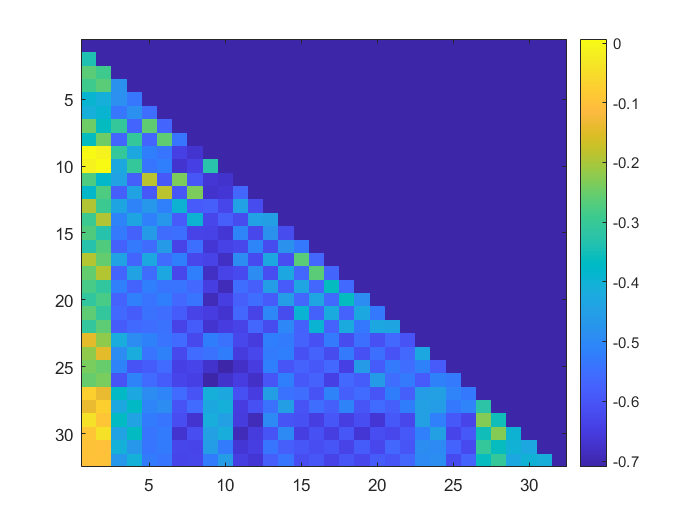

Cov = (XL * YL')/(size(X,1) - 1);
holder(indices) = Cov(:,2);
figure; imagesc(holder); colorbar;

# Continuous

% (Using level 1 motorized start, mouse 1096).
clear all;

% Load PLSR results.
load('Y:\Sarah\Analysis\Experiments\Random Motorized Treadmill\PLSR\results\level 1 continuous\Ipsa Contra\motorized_transitions_continuousVars_start\1096\PLSR_results.mat');

% Load dataset info
load('Y:\Sarah\Analysis\Experiments\Random Motorized Treadmill\PLSR\variable prep\datasets\level 1 continuous\Ipsa Contra\motorized_transitions_continuousVars_start\1096\PLSR_dataset_info.mat');

XL = PLSR_results.XL;
YL = PLSR_results.YL;
XS = PLSR_results.XS;
YS = PLSR_results.YS;
BETA = PLSR_results.BETA;
W = PLSR_results.stats.W;

X = dataset_info.explanatoryVariables;
Y = dataset_info.responseVariables;

holder = NaN(32);
indices = find(tril(ones(32), -1));



% Calculate & plot the mean difference between the two periods
% just averages from the original (normalized) dataset.

% (FYI, PLSR captures ~60% of the variation in the correlations for this
% comparison.)

rng = range(Y(:,2));
mean_rest = mean(X(Y(:,2) < 0, :),1);
mean_walk = mean(X(Y(:,2) > 0, :),1);
mean_cont_diff_real = (mean_walk - mean_rest)/rng;

% Calculate reconstructed data with W.
XnewW = XS * W';
XSnew = X * W;
YnewW = [ones(size(XnewW,1),1) XnewW]*BETA;



% Calculate mean difference between the two periods for XnewW
% (normalized)
mean_rest = mean(XnewW(Y(:,2) < 0, :),1);
mean_walk = mean(XnewW(Y(:,2) > 0, :),1);
mean_cont_diff_W = (mean_walk - mean_rest)/rng;

% (Note that this XnewW is way too small)


%Calculate reconstructed data with the XL.
XnewXL = XS * XL';

YnewW = [ones(size(XnewW,1),1) XnewW]*BETA; % too small
YnewYL = YS * YL'; % Too small
YnewXL = [ones(size(XnewXL,1),1) XnewXL]*BETA; % Close
YnewXW = [ones(size(X,1),1) X]*BETA; % Close

% Calculate mean difference between the two periods for XnewXL
% (not normalized)
mean_rest = mean(XnewXL(Y(:,2) < 0, :),1);
mean_walk = mean(XnewXL(Y(:,2) > 0, :),1);
mean_cont_diff_XL = (mean_walk - mean_rest)/rng;
%  YnewXW and YnewXL are very similar. 


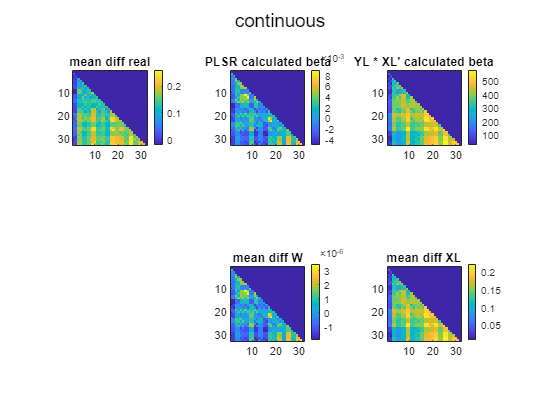

% Plot matrices next to each other.

Bxl = XL * YL';

figure; 
subplot(2, 3, 1);
holder(indices) = mean_cont_diff_real;
imagesc(holder); colorbar; title('mean diff real');axis square;

subplot(2, 3, 2);
holder(indices) = BETA(2:end, 2);
imagesc(holder); colorbar; title('PLSR calculated beta'); axis square;

subplot(2, 3, 3);
holder(indices) = Bxl(:, 2);
imagesc(holder); colorbar; title("YL * XL' calculated beta"); axis square;

subplot(2, 3, 6);
holder(indices) = mean_cont_diff_XL;
imagesc(holder); colorbar; title('mean diff XL'); axis square;

subplot(2, 3, 5);
holder(indices) = mean_cont_diff_W;
imagesc(holder); colorbar; title('mean diff W'); axis square;% Plot each weight.
sgtitle('continuous');

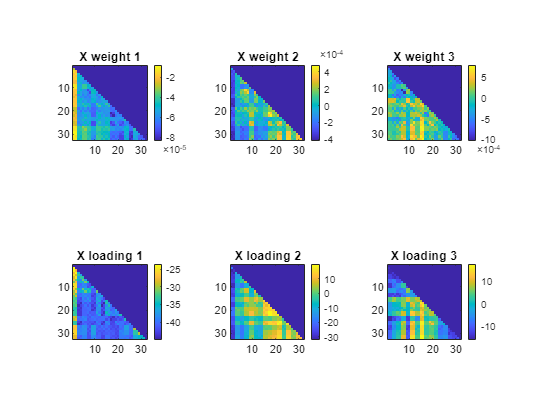

% Plot each weight
figure;
for i = 1:3
    subplot(2,3,i); 
    holder(indices) = W(:,i);
    imagesc(holder); colorbar; axis square; title(['X weight ' num2str(i)]);

    subplot(2,3,i + 3); 
    holder(indices) = XL(:,i);
    imagesc(holder); colorbar; axis square; title(['X loading ' num2str(i)]);

end

% Try to find scaling factor.
scale_cont = Bxl' ./ mean_cont_diff_XL;

% Calculate with B scaling. 
% B = XS' * YS;
% beta_rescaled = W * B' * YL';
% 
% bX = ones(size(XL)) * B;
% bY = B * ones(size(YL))';
% 
% holder(indices) = beta_rescaled( :, 2);
% figure; imagesc(holder); colorbar;



% With sum of responseVariables 
% Bpls = XL / sum(abs(Y(:,2))) * 2 * YL';
%  holder(indices) = Bpls(:,2);
%  scale = Bpls' ./ mean_cont_diff_XL;
%  figure; imagesc(holder); colorbar;

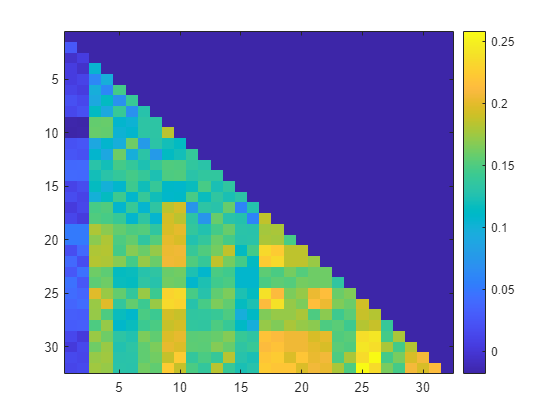

% Cov & accel
Cov = X' * Y;

CovS =  Cov./(size(X,1) - 1);
holder(indices) = CovS(:,2);
figure; imagesc(holder); colorbar;

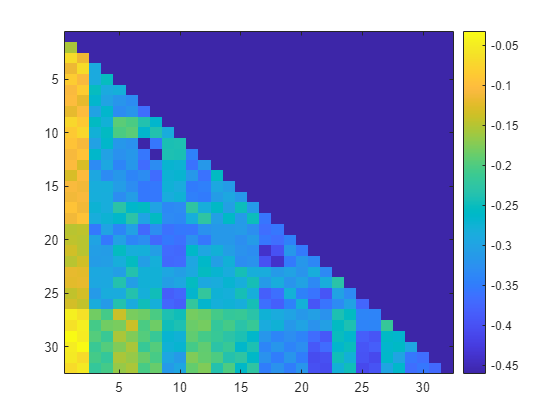

 % Cov. & speed
Cov = X' * Y;
[U, S, V] = svd(Cov, 'econ');
CovS = Cov/ (size(X,1)- 1);
holder(indices) = CovS(:,1);
figure; imagesc(holder); colorbar;


mx = max(Y(:,1));
mn = min(Y(:,1));
range = mx - mn;


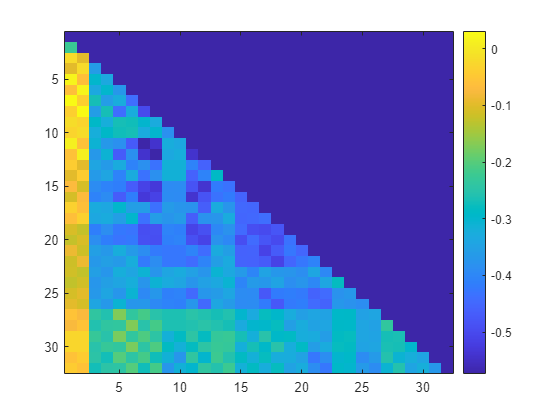


mean_speed_upper_real = mean(X(Y(:,1) == mx, :), 1);
mean_speed_lower_real = mean(X(Y(:,1) == mn, :), 1);
mean_speed_diff_real = (mean_speed_upper_real  - mean_speed_lower_real) /range;

holder(indices) = mean_speed_diff_real;
figure; imagesc(holder); colorbar;

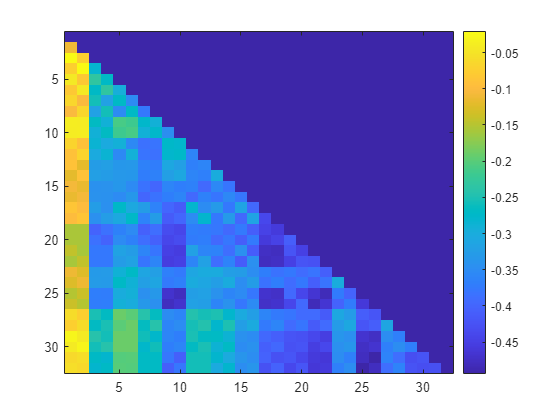

XnewXL = XS * XL';
mean_speed_upper_XL = mean(XnewXL(Y(:,1) == mx, :), 1);
mean_speed_lower_XL = mean(XnewXL(Y(:,1) == mn, :), 1);
mean_speed_diff_XL = (mean_speed_upper_XL  - mean_speed_lower_XL)/range;

holder(indices) = mean_speed_diff_XL;
figure; imagesc(holder); colorbar;

holder(indices) = Cov(:,1)/(size(X,1) - 1);
figure; imagesc(holder); colorbar;

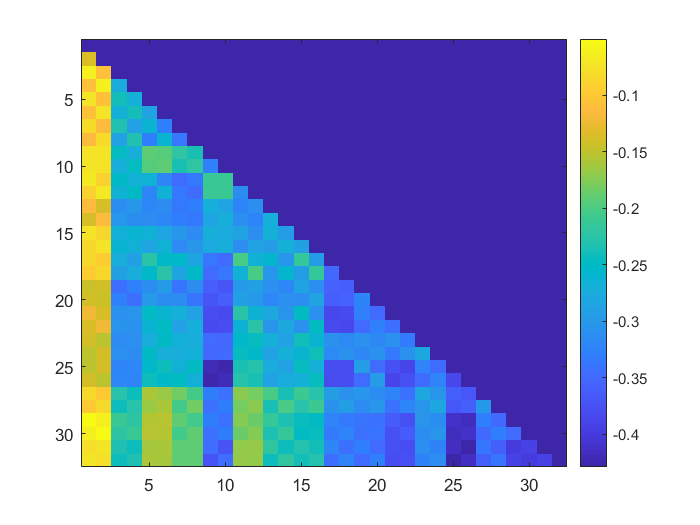


Cov = XL * YL'/(size(X,1) - 1);
holder(indices) = Cov(:,1);
figure; imagesc(holder); colorbar;